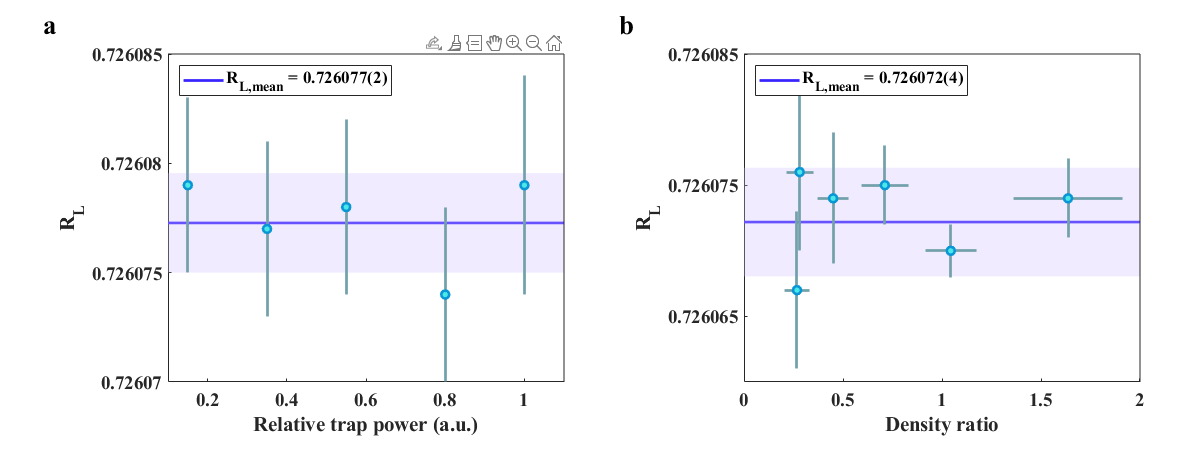


% Fig. 3 %

clear all;
close all;

loadFile = {'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\RvsI\RvsI.fig',...
    'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\RvsDensity\RvsDensity.fig'};

img1 = openfig(loadFile{1});
ax1 = img1.Children(end);
ax_c1 = ax1.Children;

img2 = openfig(loadFile{2});
ax2 = img2.Children(end);
ax_c2 = ax2.Children;


f1 = figure;


% (a) %
t1 = axes('Position',[0.14 0.15 0.33 0.73]);
copyobj(ax_c1,t1);

set(t1,'FontName',ax1.FontName,...
    'FontWeight',ax1.FontWeight,'FontSize',14);
xlim(t1,ax1.XLim);
ylim(t1,ax1.YLim);
xticks(t1,ax1.XTick);
yticks(t1,ax1.YTick);
set(t1,'XLabel',ax1.XLabel);
set(t1,'YLabel',ax1.YLabel);

legend('R_{L,mean} = 0.726077(2)','','', ...
    'Location','northwest','FontSize',13);

not1 = annotation(f1,'textbox',...
    [0.03,0.94,0.05,0.05],...
    'String','a',...
    'FontWeight','bold',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');


% (b) %
t2 = axes('Position',[0.62 0.15 0.33 0.73]);
copyobj(ax_c2,t2);

t2.Colormap = img2.Colormap;

set(t2,'FontName',ax2.FontName,...
    'FontWeight',ax2.FontWeight,'FontSize',14);
xlim(t2,ax2.XLim);
ylim(t2,ax2.YLim);
xticks(t2,ax2.XTick);
yticks(t2,ax2.YTick);
set(t2,'XLabel',ax2.XLabel);
set(t2,'YLabel',ax2.YLabel);

legend('R_{L,mean} = 0.726072(4)','','', ...
    'Location','northwest','FontSize',13);

not2 = annotation(f1,'textbox',...
    [0.51,0.94,0.05,0.05],...
    'String','b',...
    'FontWeight','bold',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');


set(f1,'Position',[100 100 1200 450],'Visible','on');

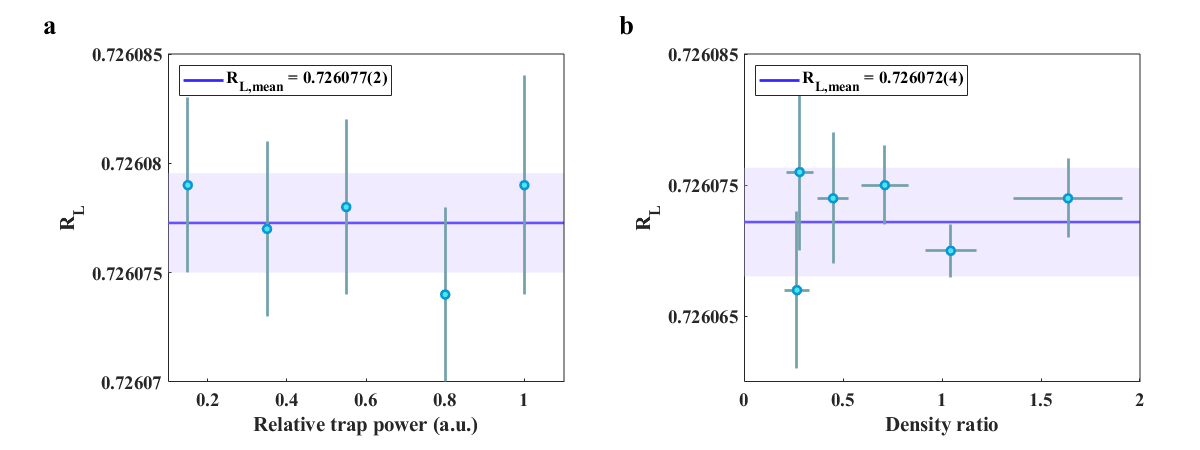


savefig(f1,'E:\Comagnetometer_Pub\Fig3\Fig3.fig');
saveas(f1,'E:\Comagnetometer_Pub\Fig3\Fig3.png');
hgexport(f1,'E:\Comagnetometer_Pub\Fig3\Fig3.eps');
hgexport(f1,'E:\Comagnetometer_Pub\Fig\Fig3.eps');
saveas(f1,'E:\Comagnetometer_Pub\Fig3\Fig3.svg');


save('E:\Comagnetometer_Pub\Fig3\Fig3.mat');